***Wireless Communications EL-GY 6023***

Homework 2 - Tommy Azzino (ta1731)

**Problem 5**

Suppose nrx=1000 RX locations are randomly located uniformly in a circle of radius

rmax = 100 m from the origin. Generate a random vector dist2 representing the

random distances from the origin of the RX locations.

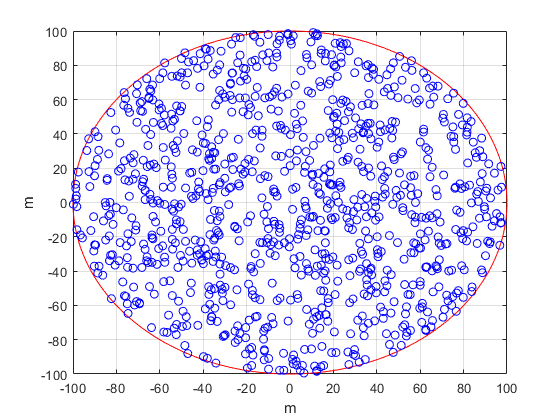

nrx = 1000;
rmax = 100;
% coordinates are generated with respect to the origin
x0 = 0; y0 = 0;
% generating random angular directions
a = rand(nrx,1)*2*pi;
% generating random rays
r = sqrt(rand(nrx,1))*rmax; % need to take the sqrt to get uniformly distributed points in the circle 
x = x0 + r.*cos(a);
y = y0 + r.*sin(a);

theta = 0:0.01:2*pi;
limit_x = x0 + rmax*cos(theta);
limit_y = y0 + rmax*sin(theta);
figure;
plot(limit_x, limit_y, 'r');
hold on;
plot(x,y,'bo');
hold off;
xlabel("m");
ylabel("m");
grid on;

% 2D distance of the random RX points from the origin (x0=0,y0=0)
dist2 = sqrt((x-x0).^2 + (y-y0).^2); 

Assuming the transmitter is at the origin at a height htx=2 m higher than the RX,

compute the distances dist to the RXs

htx = 2;
% distance of the RX points from the TX at the origin with height 2m
dist = sqrt(dist2.^2 + htx^2);

Assuming the given path loss model,

generate random path losses to the RXs. Assume $\sigma = 4$ dB and $f_c = 2.3$ GHz.

fc = 2.3e9;
sigma = 4;
% compute the PL according to the provided formula
PL = 32.4 + 14.3*log10(dist) + 20*log10(fc/1e9) + randn(size(dist)).*sigma;

Finally plot a CDF of Es/N0 with transmit power, Ptx = 15 dBm, bandwidth B = 20MHz and thermal noise N0=−170 dBm/Hz.

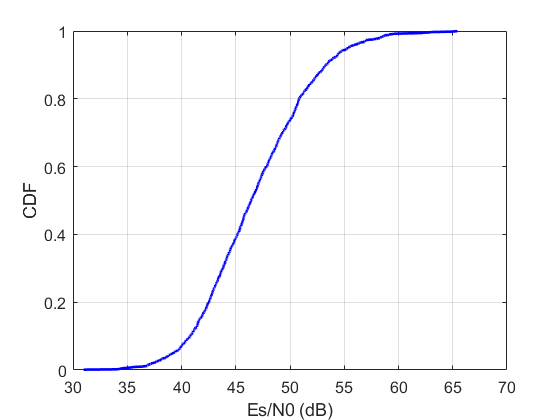

Ptx = 15; % power in dBm
B = 20e6; % bandwidth
N0 = -170; % termal noise in dBm/Hz
EsN0 = Ptx - PL - N0 - 10*log10(B); % computing Es/N0

plot(sort(EsN0), (1:nrx)/nrx,'b','Linewidth', 2);
grid on;
xlabel('Es/N0 (dB)');
ylabel('CDF');
set(gca, 'Fontsize', 12);

**Problem 6**

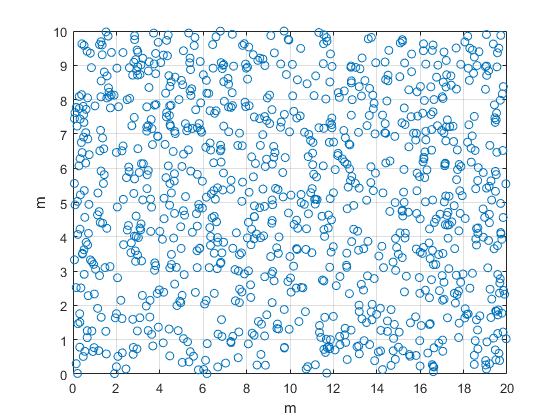

% Generating points in a squared region 
% according to some suitable indoor scenario dimension
l = 20;  % length of region in m
w = 10;  % width in m
X = rand(nrx,2).*[l w];
dist = sqrt(sum(X.^2,2)); % distances from the centre (0,0)
% plot the random points
plot(X(:,1), X(:,2), 'o');
grid on;
xlabel("m");
ylabel("m");

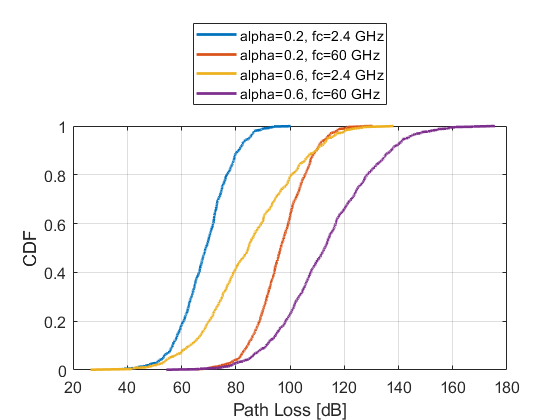

L0 = 3.4; % number found in the literature
alphas = [0.2, 0.6];
fcs = [2.4e9, 60e9]; % frequencies
PL_s = zeros(length(alphas)*length(fcs), nrx);
k=1;
p = (1:nrx)/nrx;
figure;
for i=1:length(alphas)
    for j=1:length(fcs)
        PL = indoorPL(dist,fcs(j),L0,alphas(i));
        PL_s(k,:) = PL;
        plot(sort(PL), p, "LineWidth",2);
        hold on;
        k=k+1;
    end
end
entries = [];
for i=1:length(alphas)
    for j=1:length(fcs)
        entries= [entries, ("alpha="+string(alphas(i))+", fc="+string(fcs(j)/1e9)+" GHz")];
    end
end
legend(entries(1), entries(2), entries(3), entries(4), "Location","northoutside");
xlabel("Path Loss [dB]");
ylabel("CDF");
set(gca, 'Fontsize', 12);
hold off;
grid on;

**Problem 7**

Ptx = 20; % tx power in dBm
B = 20e6; % bandwidth
N0 = -170; % noise power density in dBm/Hz

(a) What is the maximum path loss, PLmax, that the link can have to meet an SNR target

of 10 dB?

snr_target = 10; % snr target in dB
% EsN0 = Ptx - PL - N0 - 10*log10(B)
PLmax = Ptx - N0 - 10*log10(B) - snr_target;
fprintf(1, 'PLmax value is %f\n',PLmax);

PLmax value is 106.989700


(b) Suppose that the path loss is lognormally distributed.

What is the outage probability Pout = Pr(PL >= PLmax) using the value PLmax from part (a)?

PL0 = 100; % dB
sigma = 8; % dB
Pout_b = qfunc((PLmax-PL0)/sigma);
fprintf(1, 'Pout value is %f\n',Pout_b);

Pout value is 0.191137


(c )

D = 7; % dB
Pout_c = Pout_b*0.5 + qfunc((PLmax-PL0-D)/sigma)*0.3 + qfunc((PLmax-PL0-2*D)/sigma)*0.2;
fprintf(1, 'Pout value is %f\n',Pout_c);

Pout value is 0.407635


function pl = indoorPL(d, fc, L0, alpha)
    % d is the vector of distances
    % fc is the carrier frequency
    % L0 is the loss factor associated to each wall
    % alpha is the average number of walls per meter of distance
    c = physconst('Lightspeed');
    lambda = c/fc;
    % compute path loss given the provided formula
    pl = fspl(d,lambda) + L0.*poissrnd(alpha*d);
    
end